% Here is the Matlab live script that can be run to see the chi square 
%statistics when testing with the (60:50) data set
[status,sheets] = xlsfinfo('NguyenDHWPart2')%shows that 3 sheets exist

status = 'Microsoft Excel Spreadsheet'

sheets = 1×1 cell array
    {'Sheet1'}


[A,names,raw] =xlsread('NguyenDHWPart2',1);% reads the first sheet only
LN=length(names) % number of columns with names

LN = 0

A % data only

A =     0.6265
    0.9003
    1.5174
    1.6848
    1.0044
    0.6111
    1.0738
    0.7023
    2.7150
    0.9658


names % headers


names =

  0×0 empty cell array



raw % headers and data

raw = 110×1 cell array
    {[0.6265]}
    {[0.9003]}
    {[1.5174]}
    {[1.6848]}
    {[1.0044]}
    {[0.6111]}
    {[1.0738]}
    {[0.7023]}
    {[2.7150]}
    {[0.9658]}
    {[1.8268]}
    {[0.5647]}
    {[1.0221]}
    {[1.9608]}
    {[1.4774]}
    {[0.9788]}


data = A(:,1)

data =     0.6265
    0.9003
    1.5174
    1.6848
    1.0044
    0.6111
    1.0738
    0.7023
    2.7150
    0.9658


data = data(~isnan(data));
data_sorted_des = sort(data, 'descend');
target_abs = sort(data((1:60),:),'descend');
target_pre = sort(data((61:110),:),'descend');
%clear;clc
% you JUST want to create 7 sets of boot samples to see how they look!
[bootstat,bootsam] = bootstrp(7,[],target_abs);
y = target_abs(bootsam);% this will give 7 sets of bootstrap samples of the set x
disp(y)

    1.0183    0.9003    1.3078    2.1638    2.3848    0.6265    0.8025
    0.9003    0.6425    0.3860    0.7471    1.0183    0.6425    1.2354
    0.3860    1.9274    1.7433    1.4774    1.5705    1.5705    1.2999
    1.0183    1.0183    1.2354    1.2999    0.7573    0.9788    1.1898
    1.7433    1.9274    1.9274    1.7695    1.0704    1.7695    1.7452
    2.7150    0.3860    0.7023    1.6058    1.6848    0.5573    0.6425
    0.3860    1.9274    1.7433    0.6425    1.1679    1.0183    2.3848
    1.0044    1.7452    2.7150    2.5812    0.5242    2.0314    0.3860
    0.6425    0.5242    1.7695    1.7452    1.3722    2.0202    0.9237
    1.2999    0.5647    0.6425    0.7573    1.6058    0.3860    0.9790
    0.5647    0.5573    1.5174    0.7471    0.8151    0.5573    2.2293
    0.7573    1.8183    0.6425    1.4774    1.0704    2.1638    1.8268
    0.5647    2.3848    0.5242    0.9788    2.0851    2.0202    2.2293
    1.3078    1.8183    0.7023    2.0851    0.6425    0.6265    1.3722
    1.

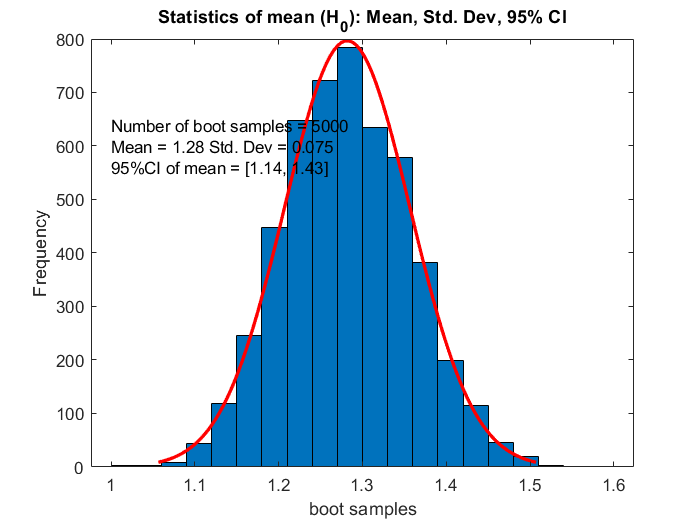

nb=5000;% number boot samples
ym=bootstrp(nb,@mean,target_abs);%5000 bootstrap sets & computes 5000 samples of the mean
histfit(ym,20) % get a histogram of the mean and a Gaussian fit
title("Statistics of mean (H_0): Mean, Std. Dev, 95% CI")
xlabel('boot samples'), ylabel('Frequency')
txt = {'Number of boot samples = 5000', 'Mean = 1.28 Std. Dev = 0.075', '95%CI of mean = [1.14, 1.43]'};
text(1,600,txt)

mean_abs = mean(ym);
std_dev_abs = sqrt(var(ym));
prctile(ym,2.5) % 2.5%

ans = 1.1402

prctile(ym,97.5) % 97.5%

ans = 1.4320


[bootstat,bootsam] = bootstrp(7,[],target_pre);
y_pre = target_pre(bootsam);% this will give 7 sets of bootstrap samples of the set x
disp(y_pre)

    3.8609    5.8181    3.8609    2.4107    6.8406    1.0142    1.3149
    4.8552    1.0142    4.8552    1.6276    3.6240    5.5987    3.2714
    2.1823    3.7794    2.3053    1.0093    3.8609    5.2802    6.8406
    7.5879    5.8203    1.3149    2.1823    7.5879    5.2802    1.7449
    6.8406    3.6240    3.8609    3.8609    2.3053    0.9912    5.8181
    1.3149    2.4107    5.1502    3.6240    2.5605    3.7963    4.5123
    7.5879    3.2714    1.8448    4.8513    5.3431    3.7794    2.3053
    1.8448    2.4107    2.7941    2.2430    7.5879    3.8609    1.3264
    1.3149    3.7963    6.8406    5.2802    2.4876    6.0584    3.2714
    3.6240    5.2802    4.4963    1.8448    2.2430    2.7941    5.5987
    2.4876    3.8609    4.8552    4.7970    2.2430    1.3264    4.7970
    5.2802    1.3264    6.0584    1.3149    5.5987    2.7941    6.0584
    5.2802    1.3264    1.0093    2.7941    2.4876    3.2714    1.0142
    1.7449    5.1502    2.4107    1.8448    2.4876    5.8203    4.8513
    4.

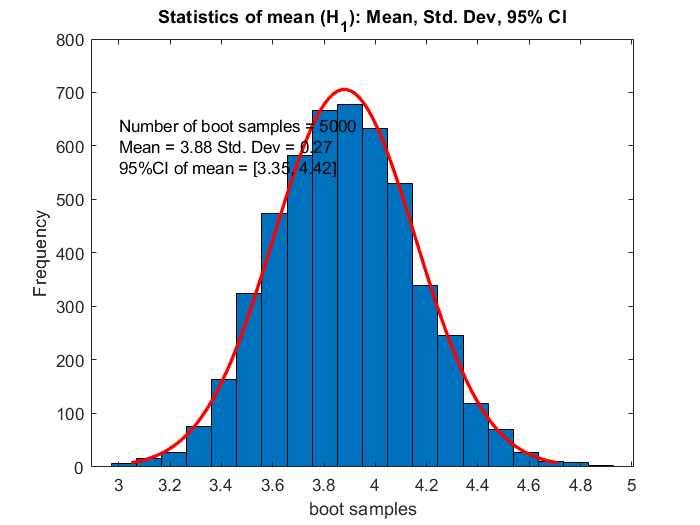

nb_pre=5000;% number boot samples
ym_pre=bootstrp(nb,@mean,target_pre);%5000 bootstrap sets & computes 5000 samples of the mean
histfit(ym_pre,20) % get a histogram of the mean and a Gaussian fit
title("Statistics of mean (H_1): Mean, Std. Dev, 95% CI")
xlabel('boot samples'), ylabel('Frequency')
txt_pre = {'Number of boot samples = 5000', 'Mean = 3.88 Std. Dev = 0.27', '95%CI of mean = [3.35, 4.42]'};
text(3,600,txt_pre)

mean_pre = mean(ym_pre);
std_dev_pre = sqrt(var(ym_pre));
prctile(ym_pre,2.5) % 2.5%

ans = 3.3610

prctile(ym_pre,97.5) % 97.5%

ans = 4.4353


resp=[zeros(N0,1);ones(N1,1)]; % labels
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,data,1);



[bootstat,bootsam] = bootstrp(7,[],data);
y_auc = data(bootsam);% this will give 7 sets of bootstrap samples of the set x
disp(y_auc)

    3.7963    1.1898    3.3433    0.5020    1.1898    1.4774    1.7449
    1.5174    5.8181    1.2354    9.2165    0.9658    1.7449    0.7767
    0.9468    0.7023    1.0704    1.3264    2.3848    0.7182    1.8055
    2.5812    5.3431    1.1898    5.7386    1.8183    2.8938    3.6240
    5.8203    3.7794    3.0247    4.3673    1.0221    1.0738    1.0738
    1.0044    1.6119    1.0183    1.5774    2.0202    5.5987    1.9274
    4.7970    1.2354    8.5828    0.9788    2.4107    0.9912    1.0142
    5.2802    3.4805    3.2714    0.7023    1.9608    0.9912    3.6240
    0.5647    0.6425    1.3149    1.3722    5.8203    1.7433    2.4876
    0.9658    3.9281    3.4805    4.5123    2.3848    1.6119    2.0202
    1.8268    2.0851    3.0247    1.7449    3.8744    1.7695    1.2354
    1.1357    3.4805    1.4774    2.2430    3.7963    2.0202    1.1679
    4.0205    4.1674    3.8744    1.0093    1.7449    0.7182    8.5828
    1.8448    1.5174    1.0738    0.9237    0.5020    0.5647    4.3673
    1.

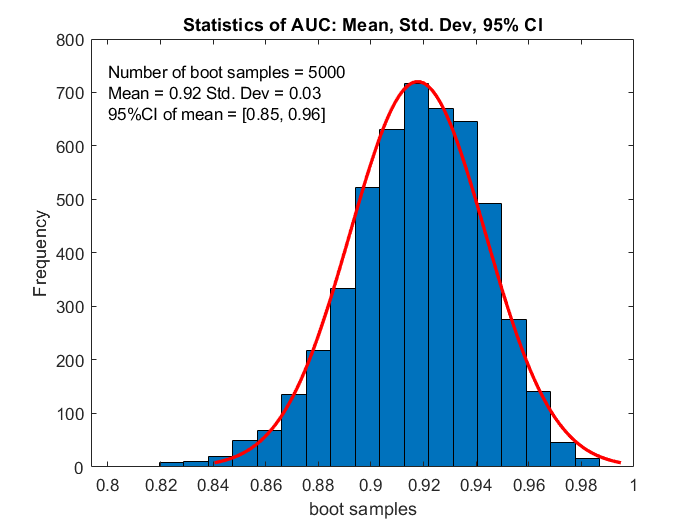

%dat=[target_abs';target_pre'];% data in a single column
nB_AUC=5000;% number of boot samples
btarea=bootstrp(nB_AUC,@calculateROCarea,resp,data);
histfit(btarea,20) % get a histogram of the mean and a Gaussian fit
title("Statistics of AUC: Mean, Std. Dev, 95% CI")
xlabel('boot samples'), ylabel('Frequency')
txt_auc = {'Number of boot samples = 5000', 'Mean = 0.92 Std. Dev = 0.03', '95%CI of mean = [0.85, 0.96]'};
text(0.8,700,txt_auc)

mean_auc = mean(btarea)

mean_auc = 0.9178

std_dev_all = sqrt(var(btarea))

std_dev_all = 0.0257

prctile(btarea,2.5) % 2.5%

ans = 0.8621

prctile(btarea,97.5) % 97.5%

ans = 0.9628

function area=calculateROCarea(resp,data)
[pf,pd,T,AUC]=perfcurve(resp,data,1);
area=AUC;
end